# ScatterBoxplot

**Overview**

The `ScatterBoxplot` chart manages a bivariate scatter plot with marginal boxplots. The chart data comprises two numeric vectors (`XData` and `YData`) . The `YData` is scattered against the `XData` on the main chart axes, and the marginal boxplots for the `XData` and `YData` are drawn on separate axes underneath and to the left of the main axes, respectively.

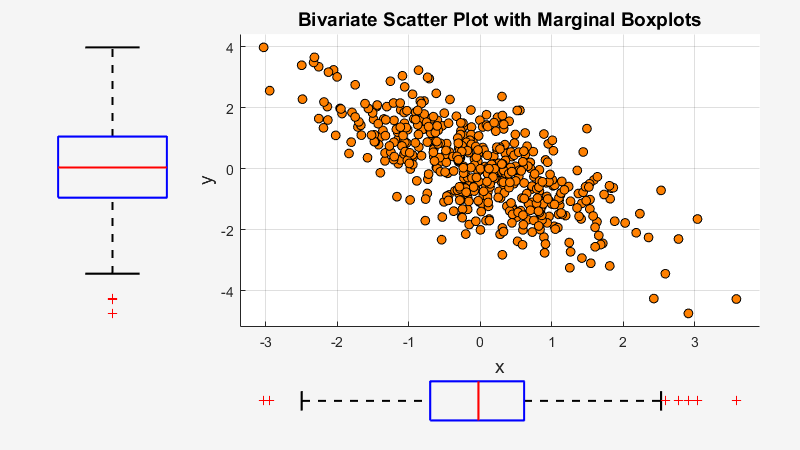

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'ScatterBoxplot.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'ScatterBoxplot'))) the source code for the `ScatterBoxplot` chart.

Documentation for [boxplot](matlab: web(fullfile(matlabroot, 'help', 'stats', 'boxplot.html'), '-helpbrowser')).

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.ScatterBoxplot

## Create some data.

rng default
x = randn( 1000, 1 );
y = 2 * x + 1 + randn( size( x ) );

## Create a figure for the chart.

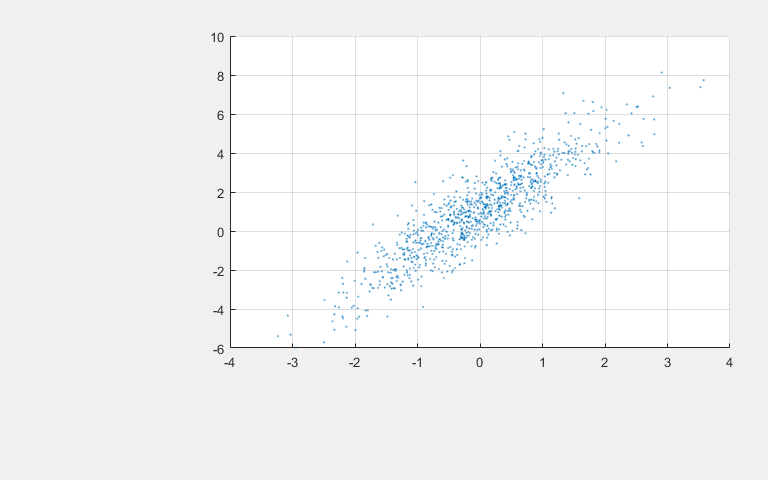

f = galleryFigure( 'Name', 'ScatterBoxPlot Example' );

## Create the chart, specifying the parent, input data and the background color.

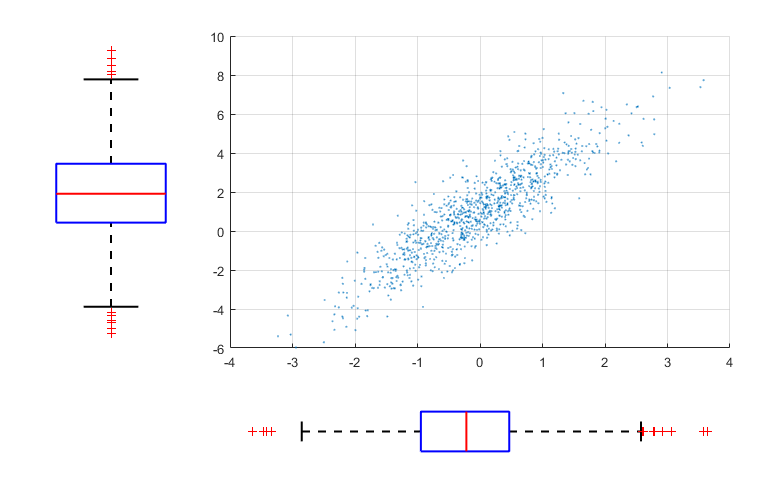

SBP = ScatterBoxplot( 'Parent', f, ...
                      'XData', x, ...
                      'YData', y, ...
                      'BackgroundColor', 'w' );

## Annotate the chart.

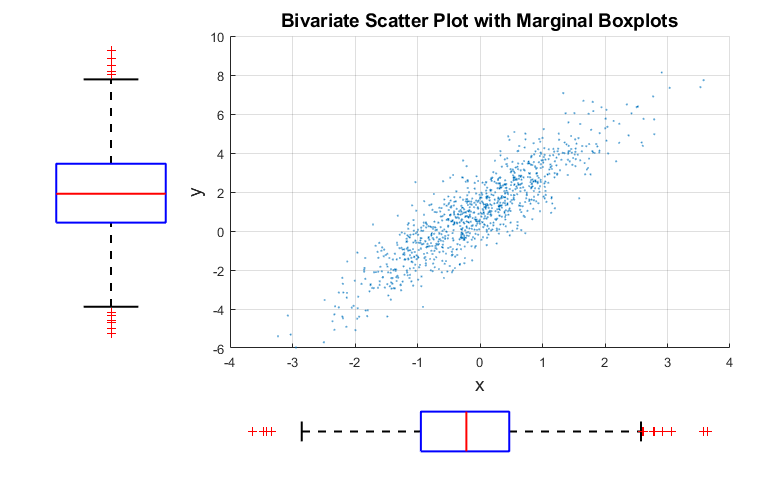

set( SBP.XLabel, 'String', 'x', 'FontSize', 14 )
set( SBP.YLabel, 'String', 'y', 'FontSize', 14 )
set( SBP.Title, ...
    'String', 'Bivariate Scatter Plot with Marginal Boxplots', ...
    'FontSize', 14 )

## Customize the chart appearance.

Create a color gradient based on the magnitude of x and y.

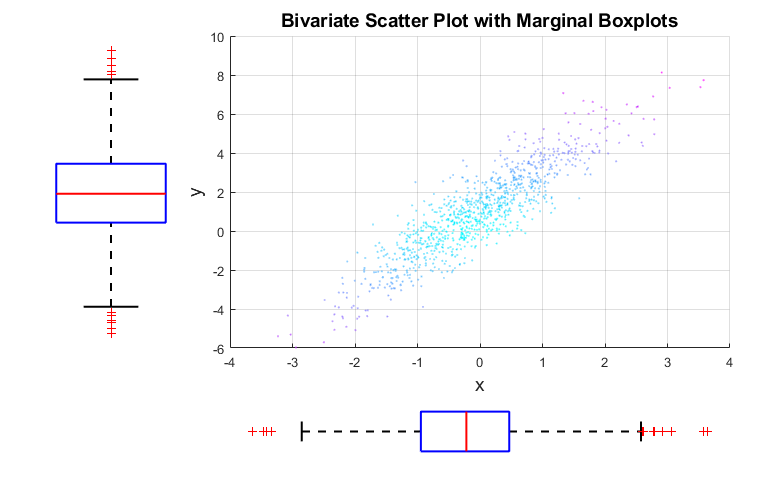

d = sqrt( x.^2 + y.^2 );
n = numel( x );
d = round( 1 + ( n - 1 ) * ( d - min( d ) ) / ( max( d ) - min( d ) ) );
map = cool( n );
map = map(d, :);
SBP.CData = map;

## Increase the marker size.

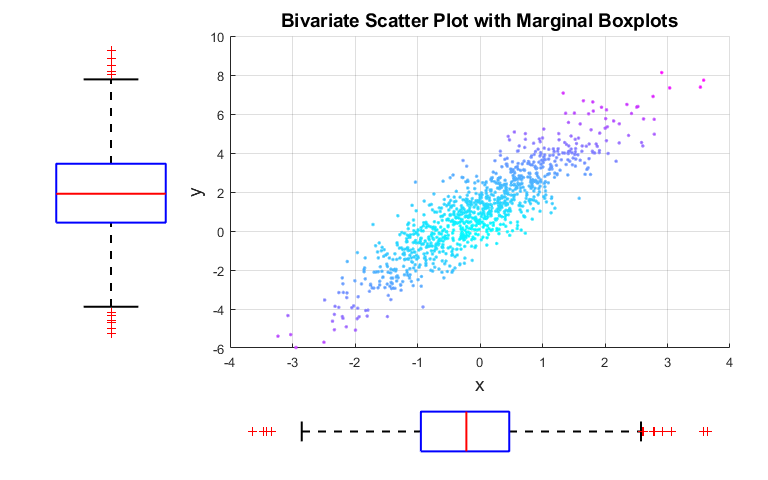

SBP.SizeData = 40;

## Change the chart data.

Truncate the x-data of the chart.

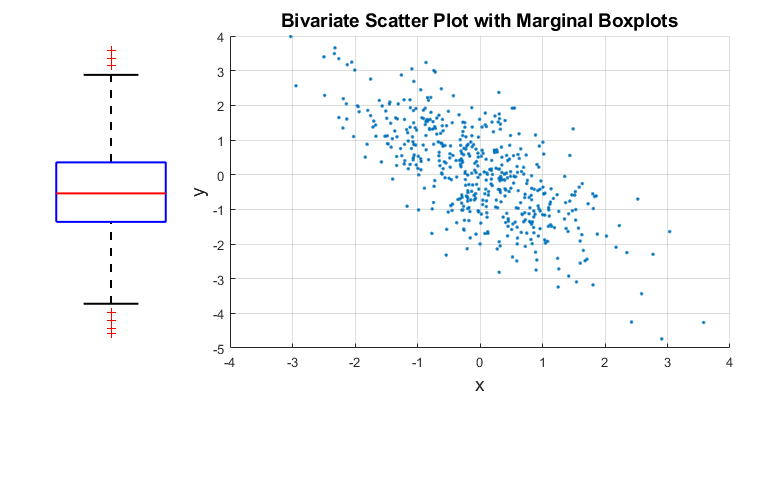

SBP.XData = x(1:500);

Update the y-data of the chart.

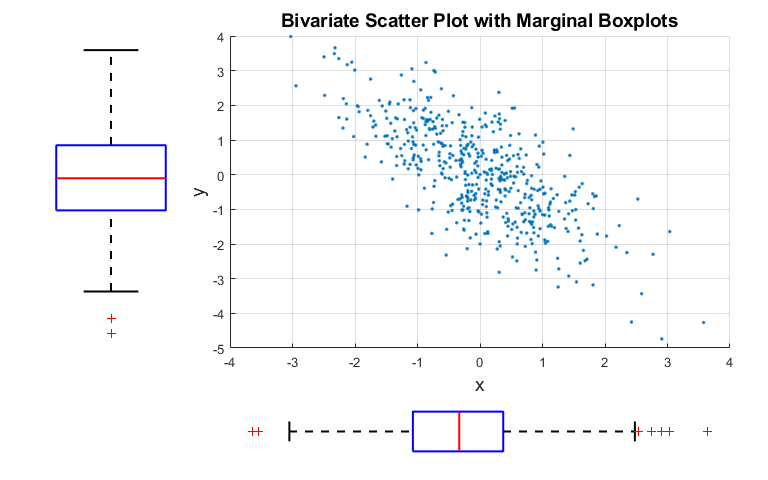

SBP.YData = (-1) * SBP.XData + randn( size( SBP.XData ) );

## Update the color data and marker.

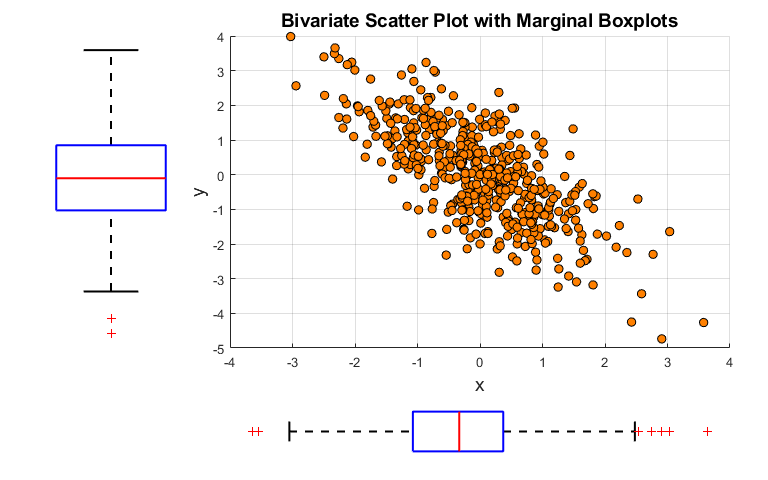

SBP.CData = [1, 0.5, 0];
SBP.Marker = 'o';
SBP.MarkerFaceColor = [1, 0.5, 0];
SBP.MarkerEdgeColor = 'k';